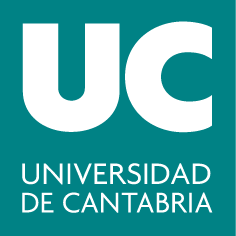

#### ***Grado en Ingeniería Química***

## **G320: Álgebra**

# **Práctica 5: Sistemas de ecuaciones lineales (II)**

*Rodrigo García Manzanas (rodrigo.manzanas@unican.es)*

*Valvanuz Fernández Quiruelas (valvanuz.fernandez@unican.es)*

**Objetivos**

- Resolución de sistemas utilizando factorización de matrices

- Resolución de sistemas mediante métodos iterativos

**Resolución de sistemas utilizando factorización de matrices**

En primer lugar, vamos a resolver el sistema del apartado *b)* del ejercicio *9* de la hoja de problemas utilizando la factorización $LU$:


$$	 	
			 \textstyle\left\{  \begin{array}{rcr}
			 x - 2y - 3z& = & 2\\ 
			 2x + y + z & = & 1\\
			 x + 3y - 2z & = & -1\\  
		 \end{array}\right.
$$


A = [1 -2 -3; 2 1 1; 1 3 -2];  % matriz coefs.
b = [2 1 -1]';  % términos indep.
[rank(A) rank([A b])]  % R-F: S.C.D.
[L, U, P] = lu(A)  % factorizacón PA = LU
P*A - L*U  % comprobación factorización (PA=LU)

Vemos que la matriz $P$ no es la identidad, lo que quiere decir que MATLAB ha realizado algún intercambio de filas en el proceso de escalonamiento de $A$. Sabemos que en estas circunstancias se cumplirá la factorización $PA=LU$, o lo que es lo mismo, $A=P^{-1}LU$. Por tanto, el sistema $A\vec{x}=\vec{b}$ podrá escribirse como $P^{-1}LU \vec{x}=\vec{b}$. Si llamamos $U\vec{x}=\vec{y}$, podremos descomponerlo en dos subsistemas (compatibles determinados) cuya resolución es muy sencilla, puesto que son triangulares: 

- 
$$1)$$
 
$$U\vec{x}=\vec{y}$$
 

- 
$$2)$$
 
$$P^{-1}L\vec{y}=\vec{b}$$


%% Resuelvo 2)
y = inv(P)*L\b
%% Resuelvo 1)
sol = U\y  % solución: (x=4/5, y=-3/5, z=0)
A*sol - b  % comprobación

Resolvamos ahora el sistema del apartado *a)* del ejercicio *10* utilizando la factorización de Cholesky:


$$			 \textstyle\left\{  \begin{array}{rcr}
			 x -y + z & = & 1\\ 
			 -x + 5y - 5z & = & 0\\
			 x - 5y + 6z & = & 1\\  
		 \end{array}\right.$$


A = [1 -1 1; -1 5 -5; 1 -5 6];  % matriz de coefs.
b = [1 0 1]';  % términos indep.
[rank(A) rank([A b])]  % R-F: S.C.D.

Antes de nada, tendremos que comprobar que la matriz $A$ admite factorización de Cholesky.

issymmetric(A)  % A simétrica
[det(A(1,1)), det(A(1:2,1:2)), det(A)]  % A definida positiva

En estas condiciones se cumplirá que $A=LL^t$, siendo $L$ una matriz triangular inferior. 

L = chol(A, 'lower')  % factorización de Cholesky
A - L*L'  % comprobación factorización

Por tanto, el sistema $A\vec{x}=\vec{b}$ podrá escribirse como $LL^t \vec{x}=\vec{b}$. Si llamamos $L^t\vec{x}=\vec{y}$, podremos descomponerlo en dos subsistemas (compatibles determinados) cuya resolución es muy sencilla, puesto que son triangulares: 

- 
$$1)$$
 
$$L^t\vec{x}=\vec{y}$$
 

- 
$$2)$$
 
$$L\vec{y}=\vec{b}$$


%% Resuelvo 2)
y = L\b
%% Resuelvo 1)
sol = L'\y  % solución: (x=5/4, y=5/4, z=1)
A*sol - b  % comprobación

**Resolución de sistemas mediante métodos iterativos**

En esta sección nos centraremos en los métodos de Jacobi y Gauss-Seidel. Pero antes, haremos una breve introducción al uso de funciones en MATLAB. Una **función** es un programa que establece una comunicación con el exterior mediante argumentos de entrada y salida. Las funciones deben guardarse en un fichero con el mismo nombre que la propia función y extensión **.m**. La estructura de cualquier función en MATLAB es la siguiente:

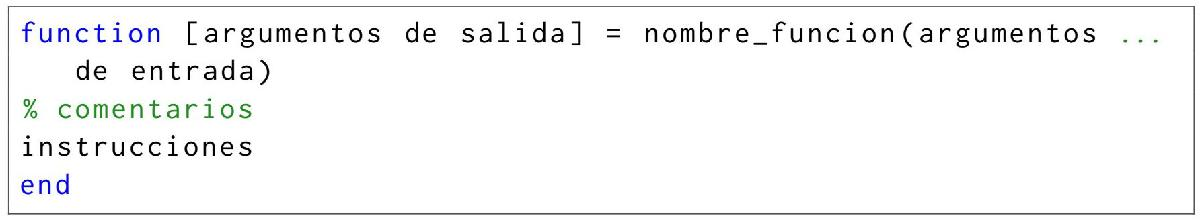

Por ejemplo, la función que se muestra a continuación permitiría calcular el área de un círculo conocido su radio:

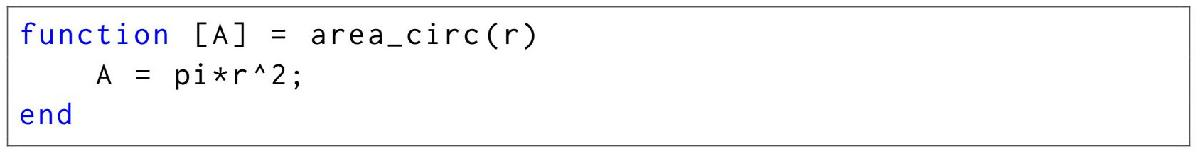

Para aplicar los métodos de Jacobi y Gauss-Seidel necesitaremos las funciones *Jacobi* y *GaussSeidel*, que puedes descargarte desde *Moodle. *Para que MATLAB reconozca estas funciones tenemos que situarnos en la misma ruta (directorio) en las que hayamos salvado los correspondientes ficheros **.m**. A partir de este momento será inmediato resolver sistemas *cuadrados* (mismo número de ecuaciones que de incógnitas), directamente desde la línea de comandos, por cualquiera de estos métodos. Como puedes ver, ambas funciones requieren como argumentos de entrada la matriz de coeficientes, el vector de términos independientes, una solución inicial (cualquiera) y el error máximo que estamos dispuestos a cometer con la solución aproximada (haz un *help* de ambas funciones). 

Como sabes, la convergencia de los algoritmos de Jacobi y Gauss-Seidel sólo está asegurada para sistemas cuya matriz de coeficientes sea *diagonalmente dominante*. Por tanto, antes de resolver el sistema que aparece a continuación por cualquiera de ambos métodos, conviene comprobar que efectivamente la matriz de coeficientes sea diagonalmente dominante:


$$\textstyle\left\{  \begin{array}{rcr}
			 10x - y - 2z & = & 6\\ 
			 x + 5y - 3z & = & 4\\
			 4x - 2y - 8z & = & 5\\
		 \end{array}\right.$$


A = [10 -1 -2; 1 5 -3; 4 -2 -8]  % efectivamente, A es diagonal. dominante, asi que la convergencia está asegurada
b = [6 4 5]'; x0 = [0 0 0]'; err = 0.001;
% Jacobi
[sol_Jacobi, niter_Jacobi] = Jacobi(A, b, x0, err)  % sol. aproximada (10 
% iteraciones)
A*sol_Jacobi - b  % comprobación
% Gauss-Seidel
[sol_GaussSeidel, niter_GaussSeidel] = GaussSeidel(A, b, x0, err)  % sol. aprox. 
% (6 iteraciones)
A*sol_GaussSeidel - b  % comprobación

#### Ejercicios propuestos

**Ejercicio 1:**

Si se puede, resuelve el siguiente sistema:

$\left\lbrack \begin{array}{cccc}
0 & 4 & 11 & -9\\
4 & 0 & -5 & 0\\
11 & -5 & 3 & -3\\
-9 & 0 & -3 & 4
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
x\\
y\\
z\\
t
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{c}
4\\
-3\\
0\\
1
\end{array}\right\rbrack$

- *a) *Utilizando la factorización $LU$(ó $PA=LU$)

- *b) *Utilizando la factorización de Cholesky

**Ejercicio 2:**

Resuelve por Jacobi y por Gauss-Seidel los siguientes sistemas. ¿Cuántas iteraciones has necesitado para llegar a una solución aproximada (con un error de $0.001$) partiendo del vector solución $\vec{0}$ en cada caso? Prueba qué ocurre al comenzar el proceso iterativo desde distintas soluciones iniciales.

*a) *$\textstyle\left\{  \begin{array}{rcr}
			 3x - y + z & = & 4\\ 
			 2x  + 5y +2z & = & -5\\
			 x + 2y +4z & = & 20\\  
		 \end{array}\right.$                *b) *$\textstyle\left\{  \begin{array}{rcr}
			 2x & = & 3\\ 
			 x + 1.5y & = & 4.5\\
			 -3y + 0.5z & = & -6.6\\  
			 2x - 2y + z + t & = & 0.8\\  
		 \end{array}\right.$                *c) *$\textstyle\left\{  \begin{array}{rcr}
			 2x - y + z & = & 1\\ 
			 3x  + 3y + 9z & = & 0\\
			 3x + 3y + 5z & = & 4\\  
		 \end{array}\right.$ 